# Predictive Maintenance of the Pick-and-Place Machines

The implementations of the statistical tests in this report are hand-crafted, with the aids of a few built-in functions `cdf()`,` icdf()`, `histcounts()`, and `norminv()`. The purpose is to avoid presenting long codes of mundane computation, so it provides a better readability for the reviewers to focus on what matters more about the testing.

## Initial setup

It is known that the settling time of the robot arms follow a normal distribution, with the mean time of 1.7 ms, and the standard deviation (SD) up to 0.5 ms, provided the arms operate at the maximum speed. Note that the codes in every sections throughout the report can be run in a stand-alone fashion, as long as the initial setup in this section has been executed firstly. 

clearvars;clc;
% load data
Robot=load('AssignmentPredictiveMaintenance.mat');
% expected value of our model
mu=1.7;
% standard deviation upper bound of our model
sigma=0.5;
% significant level (corresponding to 99% confidence level)
sig_lv=0.01;

## Hypothesis testing for mean

We now conduct a hypothesis testing with 99% confidence level.

% test 28 robot arms
for index=1:28
    speed=Robot.RobotArms(index).speed;
    time=Robot.RobotArms(index).settling_time;
    
    % data prunning
    % remove the data that do not indicate operations at the max speed
    invalid_speed=speed~=4.2;
    time(invalid_speed)=[];
    N=length(time);
    
    % sample mean
    s_mean=sum(time)/length(time);
    results(index).s_mean=s_mean;
    
    % sample variance
    s_var=sum((time-s_mean).^2)/(length(time)-1);
    s_sigma=sqrt(s_var);
    results(index).s_sigma=s_sigma;
    
    % z-statistic
    s_z=sqrt(N).*(s_mean-mu)/s_sigma;
    results(index).s_z=s_z;
    %p value
    pval=cdf("Normal",-abs(s_z),0,1)+(1-cdf("Normal",abs(s_z),0,1));
    results(index).pval=pval;
    
    % decide on H_0
    if pval<sig_lv
        report(index).ztest=1;
    else
        report(index).ztest=0;
    end
    
    % half width  
    half_width=abs(icdf('Normal',sig_lv/2,0,1)).*s_sigma/sqrt(N);
    results(index).half_width=half_width;
    
    % confidenc interval
    ci_l=s_mean-half_width;
    ci_r=s_mean+half_width;
    results(index).ci=[ci_l ci_r];
end

Since we have a sufficiently large sample size (a thousand, after pruning), by CTL we can approximate the sum of the random variables to a normal distribution. Hence it justifies the choice of Z test (using normal distribution) over T test (using t-distribution) in our scenario. 

The two hypotheses we set up are shown as the following:

- **H0**: mean = 1.7

- **H1**; mean $\not=$ 1.7

Since the mean is actually defined in the spec so it must be correct, the only interpretation remains for the rejection of H0 is to suggest the robot is malfunctioning.

Based on the p value we just computed, we will reject H0 if p value < 0.01. The statistical meaning of this concerns with the likelihood of getting the sample mean at least as extreme being less than (1 - confidence level). An example of an acceptance (i.e., fail to reject) of H0 for the robot #2 is shown below. Note that the test statistic lies within the range between the left (0.05%) and the right (99.5%) critical values. 

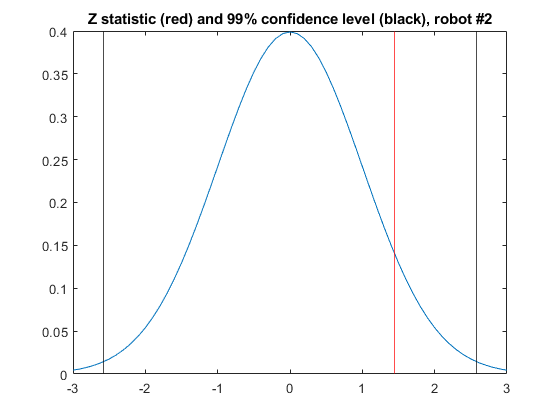

plot([-3:.1:3],normpdf([-3:.1:3]));
xline(icdf('normal',0.005,0,1),'-k');
xline(icdf('normal',0.995,0,1),'-k');
xline(results(2).s_z,'-r');
title('Z statistic (red) and 99% confidence level (black), robot #2');

Below illustrates the sample mean with the confidence interval at 99% for all 28 robots, the red horizontal line represents the mean of the hypothesized model.

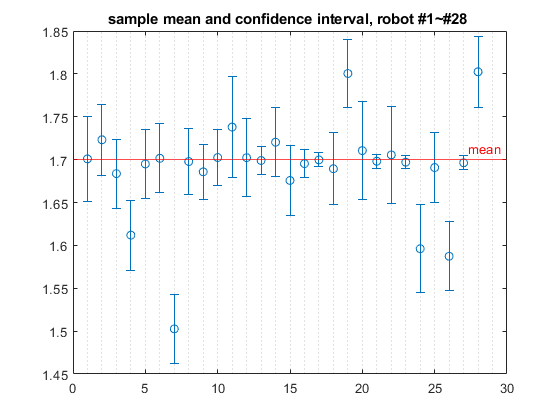

y_rob=[];
y_rob=[y_rob results.s_mean];
err=[];
err=[err results.half_width];
errorbar([1:1:28],y_rob,err,'o');
yline(mu,'-r',"mean");
set(gca,'xminorgrid','on','yminorgrid','off')
title('sample mean and confidence interval, robot #1~#28 ');

## Chi square goodness-of-fit

We now conduct a chi square testing with 99% confidence level.

for index=1:28
    speed=Robot.RobotArms(index).speed;
    time=Robot.RobotArms(index).settling_time;
    
    % data prunning
    % remove the data that do not indicate operations at the max speed
    invalid_speed=speed~=4.2;
    time(invalid_speed)=[];
    N=length(time);
    
    % bin size
    k=100;
    % critical value at 99% confidence level
    c_val_chi=icdf("Chisquare",0.99,k-1);
    
    min_chisquare=realmax;
    % try different SD value up to 0.5
    for m_sigma=sigma/100:sigma/100:sigma
        % create equiprobable bins
        x=norminv(1/k:1/k:(k-1)/k,mu,m_sigma);
        pd=makedist('Normal','mu',mu,'sigma',m_sigma);
        y=diff(cdf(pd,x));
        y=[(1-sum(y))/2 y (1-sum(y))/2];
        expcount=N*y;
        edges=[-inf x inf];
        % count the samples falling in each bin
        bincount=histcounts(time,edges);
        chisquare=sum(((bincount-expcount).^2)./expcount);
        % update
        min_chisquare=min(chisquare, min_chisquare);
    end
    
    % decide on H_0
     results(index).chisquare=min_chisquare;
        if min_chisquare>c_val_chi
            report(index).chi2=1;
        else
            report(index).chi2=0;
        end
end

The two hypotheses we set up are shown as the following:

- **H0**: the sample fits our specific normal distribution

- **H1**: the sample does not fit our specific normal distribution

For the interval between bins we choose it to be equiprobable, since it can guarantee an unbiased test (Kendall and Stuart, 1979), that is, the test is more likely to reject H0 when it is false than when it is true. As for the number of bins, we want it to be as many as it can be, such that the information will not be lost due to the coarse granularity. However, we also have to ensure the expected counts inside each bin is $\ge$ 5, a general guideline mentioned in the textbook (Law), in order to retain the test validity. Consequently, we argue that a bin size of k =100 is a reasonable choice for our situation.

Using robot #28 as example. we show the expected counts of the hypothesized normal distribution, along with the counts in each bin interval for the sample. The H0 is rejected because the chi square statistic is larger than the critical value at 99% confidence. Even by checking visually, it is apparent to determine the discrepancy between the two distributions is large, as shown in the plot below:

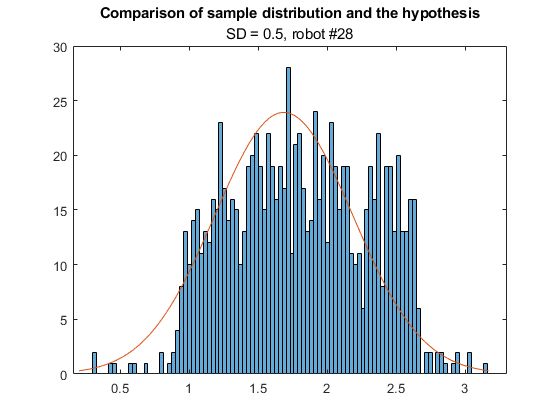

histogram(time,k);
hold on;
step=(6*sigma)/k;
plot([mu-3*sigma:step:mu+3*sigma-step],N*diff(cdf(pd,[mu-3*sigma:step:mu+3*sigma])));
title('Comparison of sample distribution and the hypothesis', 'SD = 0.5, robot #28');
hold off;

### Chi-square test for variance

We now conduct a chi square testing with 99% confidence level for the variance.

for index=1:28
    speed=Robot.RobotArms(index).speed;
    time=Robot.RobotArms(index).settling_time;
    
    % data prunning
    % remove the data that do not indicate operations at the max speed
    invalid_speed=speed~=4.2;
    time(invalid_speed)=[];
    N=length(time);
    
    % sample mean
    s_mean=sum(time)/length(time);
    results(index).s_mean=s_mean;
    
    % sample variance
    s_var=sum((time-s_mean).^2)/(length(time)-1);
    s_sigma=sqrt(s_var);
    results(index).s_sigma=s_sigma;
    
    % critical value at 99% confidence level
    c_val_chi_var=icdf("Chisquare",0.99,N-1);
    
    var_chisquare=(N-1).*s_var/(sigma.^2);
    results(index).var_chisquare=var_chisquare;
    if var_chisquare>c_val_chi_var
        report(index).chi2_var=1;
    else
        report(index).chi2_var=0;
    end
end

The two hypotheses we set up are shown as the following:

- **H0**: variance = 0.5

- **H1**: variance > 0.5

The test is one-tailed because the spec allows the variance to be smaller than 0.5, therefore we only look at the right hand side. If the chi statistic > critical value, then H0 will be rejected.

## Kolmogorov-Smirnov goodness-of-fit

We now conduct a K-S testing with 99% confidence level.

for index=1:28
    speed=Robot.RobotArms(index).speed;
    time=Robot.RobotArms(index).settling_time;
    
    % data prunning
    % remove the data that do not indicate operations at the max speed
    invalid_speed=speed~=4.2;
    time(invalid_speed)=[];
    N=length(time);
    
    quantile=sort(time.');
    emp_cdf=[];
    for n=1:N
        emp_cdf=[emp_cdf sum(quantile(:)<=quantile(n))/N];
    end
    % critical value at 99% confidence level
    c_val_ks=1.628/(sqrt(N)+0.12+(0.11/sqrt(N)));
    
    min_d_n=realmax;
    % try different SD value up to 0.5
    for m_sigma = sigma/100:sigma/100:sigma
        pd = makedist('Normal','mu',mu,'sigma',m_sigma);
        norm_cdf=cdf(pd,quantile);
        % compute the max vertical difference
        d_plus=max(emp_cdf-norm_cdf);
        % comput at the same point, with the value "just before"
        d_minus=max(norm_cdf-(emp_cdf-1/N));
        % take the larger one
        d_n=max(d_plus,d_minus);
        % update
        min_d_n=min(min_d_n,d_n);
    end
        results(index).d_n=min_d_n;
    % decide on H_0
    if min_d_n>c_val_ks
        report(index).ks=1;
    else
        report(index).ks=0;
    end
end

The two hypotheses we set up are shown as the following:

- **H0**: the sample fits our specific normal distribution

- **H1**: the sample does not fit our specific normal distribution

Note that the hypotheses we have in the K-S test are the same as they are in the chi square test. The two testings are both used to test the goodness-of-fit, i.e., describe whether the observed sample comes from a specific distribution.

The K-S test avoids the guessing work of binning size, by comparing the empirical CDF of the sample to that of the hypothesized distribution. The maximum difference of the two CDFs is computed. If the test statistic > critical vale, then reject H0.

Once again, using robot #28 as example. The H0 is rejected, and we can clearly see the reason, as there are large vertical differences seen at the both tails of the distribututions.

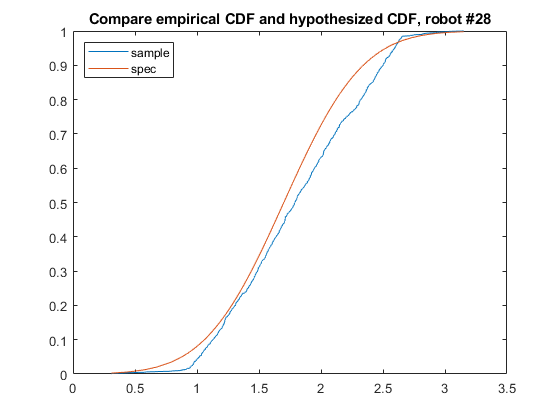

plot(quantile,emp_cdf);
hold on;
plot(quantile,norm_cdf);
title('Compare empirical CDF and hypothesized CDF, robot #28');
legend('sample','spec','Location','northwest');
hold off;

## Conclusion

The following table displays the results for all 28 robots of the above mentioned tests, where **1** denotes rejection of H0, and **0 **denotes acceptance.

report

report = 1×28 struct array with fields:
    ztest
    chi2
    chi2_var
    ks


Since the we have tested for the mean (Z test) and the variance (chi square for variance) separately, we argue that taking the union of H0 rejections from both tests will reflect whether our sample is truly consistent with the normal distribution which described by the spec. Hence we could combine both tests and regard them as one testing about malfunctioning.

Furthermore, we are optimistic with the data, such that if any of the three tests (namely the "combined test", chi square test, and KS test) fail to reject H0 of an individual robot, then we determine that particular robot is working normally. The final result of our malfunctioning robots is as the following.

broken=[];
for index=1:28
    if bitor(report(index).ztest,report(index).chi2_var).*report(index).chi2.*report(index).ks == 1
        broken=[broken index];
    end     
end
broken

broken =      1     4     7    11    20    22    24    26    28


## Appendix

The various tests statistics and parameters for all 28 robots are included in the following table

results

results = 1×28 struct array with fields:
    s_mean
    s_sigma
    s_z
    pval
    half_width
    ci
    chisquare
    var_chisquare
    d_n
